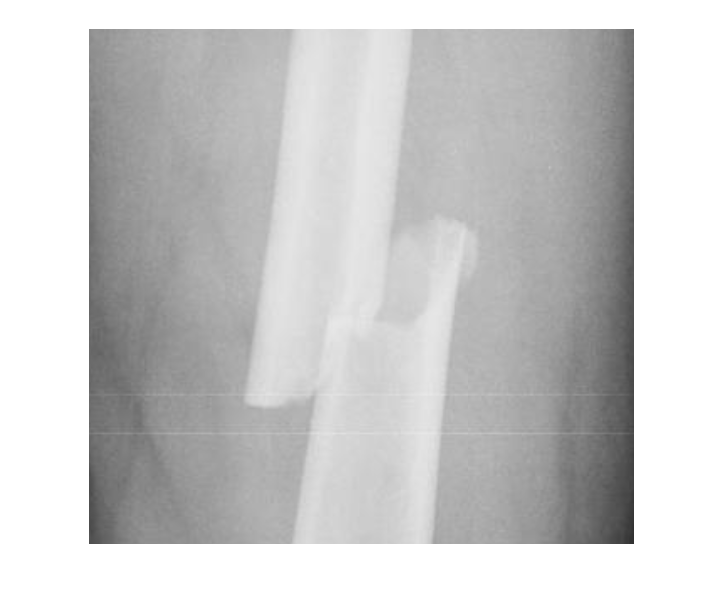

%compound fractures femur shaft xray
clear all
clc
close all
name= input('Enter file name: ','s');
I = imread(name);
Ig = rgb2gray(I);
 imshow(Ig)

max = Ig(1,1)

max = uint8
140

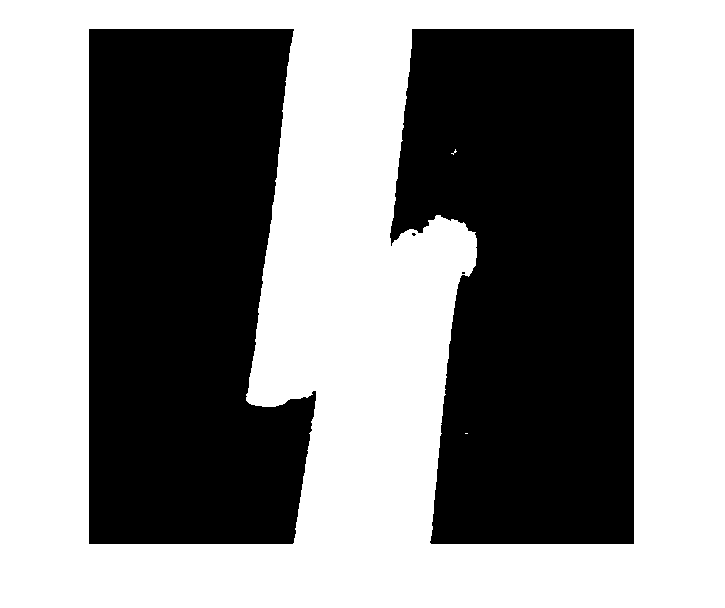

[q,w] = size(Ig);
for i = 1:q
    for j = 1:w
        if max<= Ig(i,j)
            max=Ig(i,j);
        end
    end
end

p = max - 35;
Ib = Ig > p & Ig < 250;

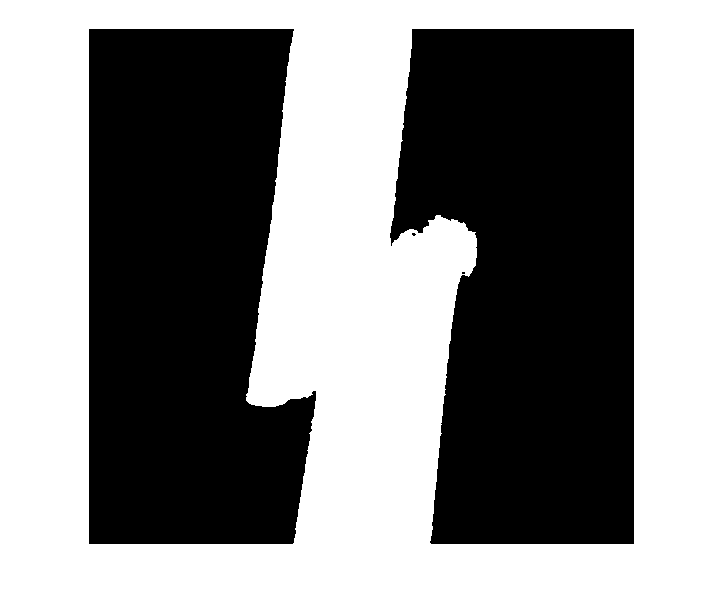

Ib = bwareaopen(Ib,50);
imshow(Ib)

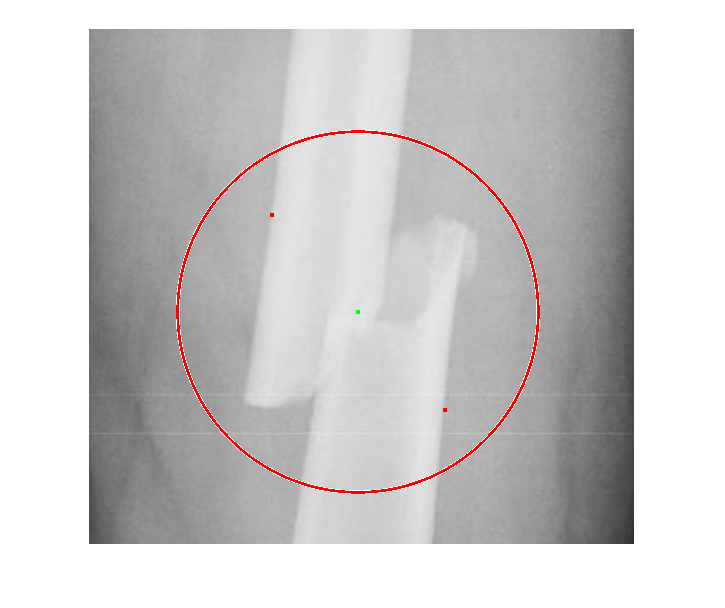

Fracture detected, length of fracture is about:


  260.6799



pixels



x1 = [];

[~,threshold] = edge(Ib,'sobel');
fudgeFactor = .5;
Ibw = edge(Ib,'sobel',threshold * fudgeFactor);

se90 = strel('line',3,90);
se0 = strel('line',3,0);
BWsdil = imdilate(Ibw,[se90 se0]);


BWdfill = imfill(BWsdil,'holes');

[r,c]=size(BWdfill);
distance=[]; %vector to store distance between white pixel
val=[];
y1=0;

for ii=1:1:r
    for jj=1:1:c %one for loop going forwards to find 1st white pixel
        if BWdfill(ii,jj)==1
            w1=[ii,jj];
            break 
        end        
        %put a break when first white found  
    end
    for kk=c:-1:1 %loop going backwards to find last white pixel
        if BWdfill(ii,kk)==1
            w2=[ii,kk];
            break
        end
    end
    distance=[distance (kk-jj)]; %storing distance between pixels
    % need to compare next distance to the previous one
    if length(distance)>1
        if (distance(end)-distance(end-1)>30 || distance(end-1)-distance(end)>30) && distance(end)-distance(end-1)<100 
            if length(val) ==2
            val=[val w2];
            y1 = w2;
            end
            if length(val)==0
            val=[val w1];
            x1 = w1;
            end
            %fracture is present, need to draw circle !!!!!!!!!!!!!!!!
            if length(x1) > 1 && length(y1) > 1
                break
            end
        end
    end
end

seD = strel('square',1);
BWfinal = imerode(BWsdil,seD);
BWfinal = imerode(BWfinal,seD);

for ii=r:1:1
    for jj=1:1:c %one for loop going forwards to find 1st white pixel
        if BWdfill(ii,jj)==1
            y1=[ii,jj];
        end
    end
end

imshow(I)
hold on
if length(x1) > 1
    y1 = w2;
    if 40 < y1(1) - x1(1) || 40 < y1(2) - x1(2)
    a = x1(1);
    b = x1(2);
    c = y1(1);
    d = y1(2);

plot(b, a, 'r.', 'MarkerSize', 10);
plot(d, c, 'r.', 'MarkerSize', 10);
mx = (a+c)/2;
my = (b+d)/2;
plot(my, mx, 'g.', 'MarkerSize', 10);

u = sqrt((c -mx)^2 + (d-my)^2);
viscircles([my,mx],u+50); %adding circle to image

hold off
length = sqrt((c-a)^2 + (b-d)^2); %calculate length of fracture

disp("Fracture detected, length of fracture is about:");
disp(length)
disp('pixels')
    else
        display('No Fracture Detected');
    end
else
    display('No Fracture Detected');
end